# Deep Learning with Point Clouds

After you have exported the labeled data, load the labels into the workspace

load gTruth

If this is the first time you are running this script, be sure to use the code below so that the gTruth knows where the 'parkingLotTrain' folder is saved on your computer. 

firstTime = false;
if firstTime
    oldPath = gTruth.DataSource.SourceName;

    % Replace this in with the location of the parkingLotTrain folder. 
    newPath = "C:\Users\parkingLotTrain";

    alternativePaths = {[oldPath newPath]};
    unresolvedPaths = changeFilePaths(gTruth,alternativePaths);

    % save the updated gTruth
    save gTruth gTruth
end

## Import Labeled Data

Create datastores to access all the data and associate these labels with the corresponding point clouds.

[pcds,bxds] = lidarObjectDetectorTrainingData(gTruth, "SamplingFactor",1);
dsTrain = combine(pcds, bxds);
preview(dsTrain)

ans = 1×3 cell array
    {1×1 pointCloud}    {4×9 double}    {4×1 categorical}


The first cell contains the point cloud, the second contains the bounding boxes, and the third contains the labels for each bounding box. [Bounding boxes are represented as described below](https://www.mathworks.com/help/lidar/ref/lidarobjectdetectortrainingdata.html#mw_cffbfb61-35f4-405a-a106-90398d206b0e):

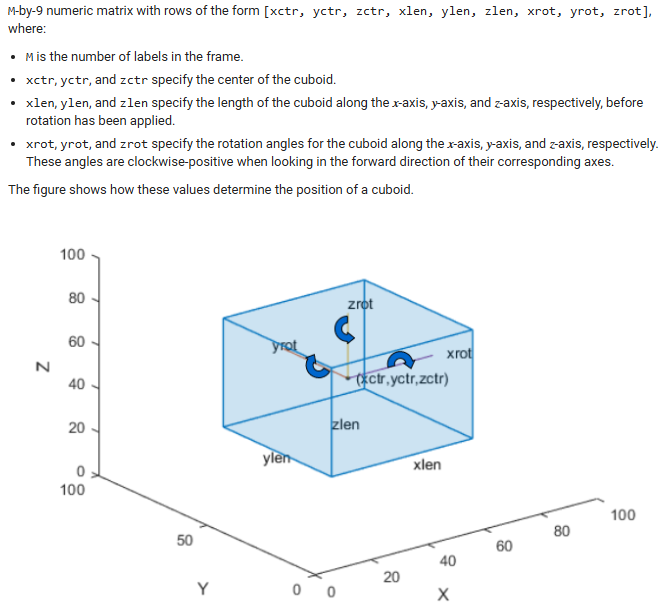

## Augment the Data

Augmentation is a great way to make your dataset, and therefore your object detector, more robust. Use the `sampleLidarData` function to collect point cloud samples from each of the classes present in the data. For example, the image below shows a sample of the 'car' class.

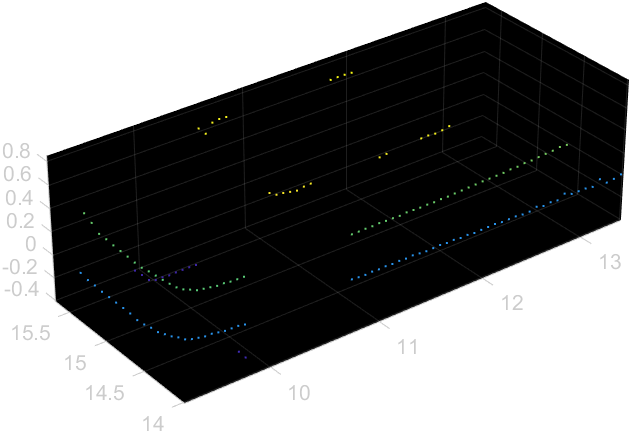

classNames = ["car", "barrel", "cone"]; 
sampleLocation = fullfile(pwd, "parkingLotSampled");
[ldsSampled,bdsSampled] = sampleLidarData(dsTrain,classNames,...
    WriteLocation=sampleLocation,Verbose=false);
dsSampled = combine(ldsSampled,bdsSampled);

Then apply the 'pcBboxOversample' function to insert these samples into each point cloud, ensuring that each point cloud will have at least 3 of each object. This artificially creates more data to train the network with. The images below are an example of what this might look like.

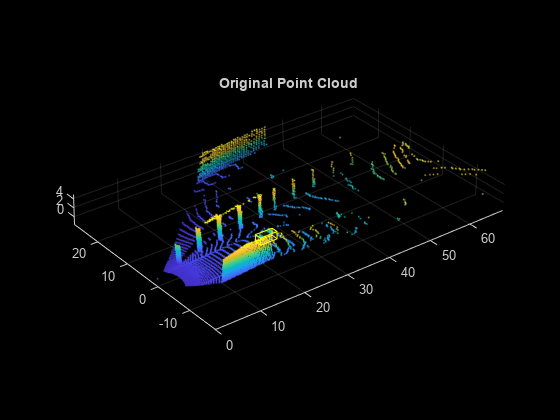 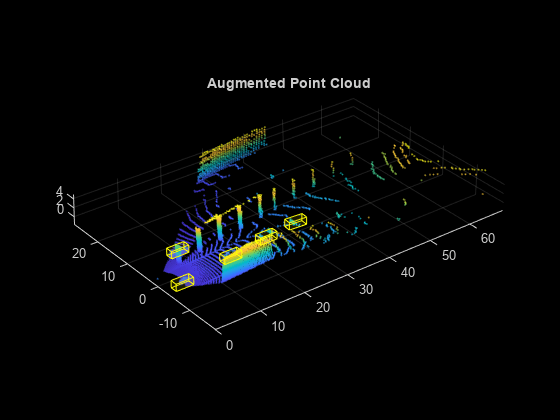

totalObjects = 3;
dsOversampled = transform(dsTrain,...
    @(x)pcBboxOversample(x,dsSampled,classNames,totalObjects));

sampledExample = preview(dsOversampled)

sampledExample = 1×3 cell array
    {1×1 pointCloud}    {10×9 double}    {10×1 categorical}


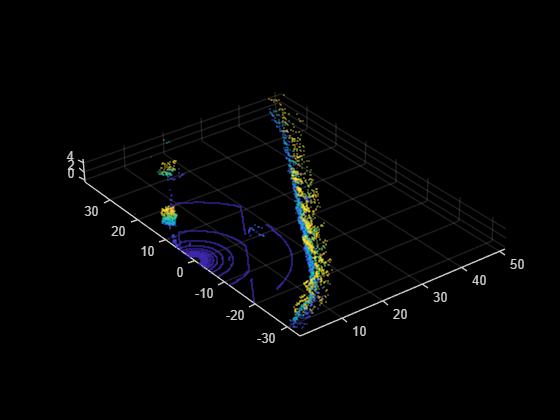

pcshow(sampledExample{1})

For more ideas on how to augment your data, check out this [documentation page](https://www.mathworks.com/help/lidar/ug/data-augmentations-for-lidar-object-detection-networks.html)!

## Train a PointPillars Network

#### 1. Configure Object Detector

Specify the class names, [anchor boxes](https://www.mathworks.com/help/vision/ug/anchor-boxes-for-object-detection.html), point cloud range. The point cloud range is based on the standard front-view parameters, which the pre-trained network used, except for instances where our point cloud data did not extend far enough. Learn more about the standard front-view point cloud range at this [documentation page](https://www.mathworks.com/help/lidar/ug/object-detection-using-pointpillars-network.html#Lidar3DObjectDetectionUsingPointPillarsExample-3). 

anchorBoxes = calculateAnchorsPointPillars(gTruth.LabelData);

xMin = 0;
xMax = 69.12;
yMin = -39.68; 
yMax = 39.68;
zMin = -0.5157;
zMax = 5;
pcRange = [xMin, xMax, yMin, yMax, zMin, zMax];

pretrainedDetector = load("pretrainedPointPillarsDetector.mat","detector");
oldDetector = pretrainedDetector.detector;

detector = pointPillarsObjectDetector(oldDetector.Network,pcRange,classNames,anchorBoxes);

#### 2. Specify training options

Learn more about the training options for point pillars object detectors [here](https://www.mathworks.com/help/lidar/ref/trainpointpillarsobjectdetector.html?searchHighlight=trainPointPillarsObjectDetector&s_tid=srchtitle_support_results_1_trainPointPillarsObjectDetector#mw_7663b7b8-8b82-4ffb-acc1-aec89ae3a13a).

options = trainingOptions('adam',...
    'MaxEpochs',60,...
    'MiniBatchSize',3,...
    'GradientDecayFactor',0.9,...
    'SquaredGradientDecayFactor',0.999,...
    'LearnRateSchedule',"piecewise",...
    'InitialLearnRate',0.0002,...
    'LearnRateDropPeriod',15,... 
    'LearnRateDropFactor',0.8,...
    'BatchNormalizationStatistics','moving',...
    'ResetInputNormalization',false);

#### 3. Train Object Detector

Run this section if you want to train a neural network...

[detector,info] = trainPointPillarsObjectDetector(dsOversampled,detector,options);

... or uncomment and run this line of code to load one that has already been trained. 

% load detector

## Use on New Data

Once your detector is trained and tested, you can start using it to make predictions on unlabeled data. We'll make predictions on the point clouds in the 'parkingLotTest' folder, and use a [`pcplayer`](https://www.mathworks.com/help/vision/ref/pcplayer.html) to visualize the predictions. 

% Create a datastore of point clouds
location = './parkingLotTest/';
fds = fileDatastore(location,"ReadFcn",@pcread, 'FileExtensions', '.pcd');

% Create a point cloud viewer
player = pcplayer([xMin xMax],[yMin yMax],[zMin zMax]);

% Make and visualize detections
while isOpen(player) && hasdata(fds)
    ptCloud = read(fds);

    view(player,ptCloud);
    ax = player.Axes;

    [bboxes,scores,labels] = detect(detector,ptCloud,"Threshold",0.4);

    bboxCar=bboxes(labels'=="car",:);
    bboxCone=bboxes(labels'=="cone",:);
    bboxBarrel=bboxes(labels'=="barrel",:);

    showShape("cuboid",bboxCar,Color="green",Parent=ax,Opacity=0.3,LineWidth=1);
    hold on;
    showShape("cuboid",bboxCone,Color="red",Parent=ax,Opacity=0.3,LineWidth=1);
    showShape("cuboid",bboxBarrel,Color="blue",Parent=ax,Opacity=0.3,LineWidth=1);
end 

Once you have a 3d object detector that you're happy with, save it to a .MAT file!

save detector detector